clear, clc

# Resource allocation after Hurricane Harvey

**How to use the template**

There are many organize and communicate your results. To help ensure your peer-reviewers can accurately grade your report, this report includes the titles for the 4 required sections in Heading 1 style. Each required element for a given section has a Heading 2 area for you to place the final result. 

Make sure to place your required findings in the appropiate area for your peer-reviewer to easily find them.

Also, only the heading titles are present.* The script is not broken into sections*.

## Background and Scope

### Import the Data

You may use an import function. If not using an import function, include the code used to import the data (it may be generated from the Import Tool)

Script for importing data from the following text file:

Auto-generated by MATLAB on 15-Sep-2022 09:36:29

opts = delimitedTextImportOptions("NumVariables", 24);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["EpisodeID", "Event_ID", "State", "Year", "Month", "Event_Type", "CZ_Name", "Begin_Date_Time", "Timezone", "End_Date_Time", "Injuries_Direct", "Injuries_Indirect", "Deaths_Direct", "Deaths_Indirect", "Damage_Property", "Property_Cost", "Damage_Crops", "Crop_Cost", "Begin_Lat", "Begin_Lon", "End_Lat", "End_Lon", "Episode_Narrative", "Event_Narrative"];
opts.VariableTypes = ["double", "double", "categorical", "double", "categorical", "categorical", "categorical", "datetime", "double", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Event_Narrative", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["State", "Month", "Event_Type", "CZ_Name", "Episode_Narrative", "Event_Narrative"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Begin_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, "End_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "ThousandsSeparator", ",");

% Import the data
StormEvents2017finalProject = readtable("D:\archive\Coursera\MATLAB data analysis\Course 1\StormEvents\StormEvents_2017_finalProject.csv", opts)

StormEvents2017finalProject = 57005×24 table
    EpisodeID      Event_ID         State         Year     Month            Event_Type                               CZ_Name                           Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                             

clear opts % clear temporary variables

### Two States Most Impacted by Harvey

Clearly state the two states in order 

According to [Wikipedia](https://en.wikipedia.org/wiki/Hurricane_Harvey), hurricane Harvey occured from 17 August, 2017 to 2 September, 2017. Therefore, only the events from this duration are listed

HurricaneEvents = StormEvents2017finalProject( ...
    datetime(2017,8,17) <= StormEvents2017finalProject.Begin_Date_Time & ...
StormEvents2017finalProject.End_Date_Time <= datetime(2017,9,2),:);

In this case, we assume the missing values as no damage to property cost and crop cost. The total cost equals to the sum of property cost and crop cost. After that, we summarize the table by states and sum all total cost by each state.

% replace missing variables with 0 (assume no damage property cost and
% crop cost for NaN inputs
HurricaneEvents.Property_Cost(ismissing(HurricaneEvents.Property_Cost)) = 0;
HurricaneEvents.Crop_Cost(ismissing(HurricaneEvents.Crop_Cost)) = 0;
% sum property cost with crop cost as total cost
HurricaneEvents.Total_Cost = HurricaneEvents.Property_Cost ...
    + HurricaneEvents.Crop_Cost;
% categorize all events by states. Sum total cost for each state and
% reordering from largest to smallest total cost
totalCostByStates = groupsummary(HurricaneEvents,"State","sum", ...
    "Total_Cost","IncludeMissingGroups",false);
totalCostByStates = sortrows(totalCostByStates,"sum_Total_Cost","descend", ...
    "MissingPlacement","last")

totalCostByStates = 56×3 table
        State         GroupCount    sum_Total_Cost
    ______________    __________    ______________

    TEXAS                268          7.7493e+10  
    LOUISIANA             85          7.5277e+07  
    NEBRASKA              62          1.6154e+07  
    NORTH CAROLINA        58          1.2338e+07  
    WASHINGTON             2               4e+06  
    FLORIDA               68           2.237e+06  
    MINNESOTA             21           1.625e+06  
    MISSISSIPPI           39            9.15e+05  
    NEW YORK             109            6.41e+05  
    TENNESSEE             38            5.04e+05  
    IOWA                  54            4.98e+05  
    PENNSYLVANIA         203          4.9163e+05  
    KENTUCKY              20            4.35e+05  
    INDIANA                6               3e+05  
    NORTH DAKOTA          17            1.43e+05  

The 2 states which has the highest total cost is shown below:

% extract 2 most damaged states
State1 = totalCostByStates.State(1);
State2 = totalCostByStates.State(2);
totalCostByStates([1 2], "State")

ans = 2×1 table
      State  
    _________

    TEXAS    
    LOUISIANA


### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

HurricaneEvents(ismember(HurricaneEvents.State,totalCostByStates.State([1,2])),:)

ans = 353×25 table
    EpisodeID      Event_ID     State    Year    Month        Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                             

## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

HarveyEventTypes = HurricaneEvents(ismember(HurricaneEvents.State,totalCostByStates.State(1:2)),:);
HarveyEventTypes = groupsummary(HarveyEventTypes,"Event_Type");
HarveyEventTypes = HarveyEventTypes(HarveyEventTypes.GroupCount>0,:)

HarveyEventTypes = 11×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood             179    
    Flood                    16    
    Funnel Cloud              3    
    Hail                      3    
    Heat                     30    
    Heavy Rain                2    
    Hurricane                 9    
    Storm Surge/Tide         10    
    Thunderstorm Wind        24    
    Tornado                  33    
    Tropical Storm           44    


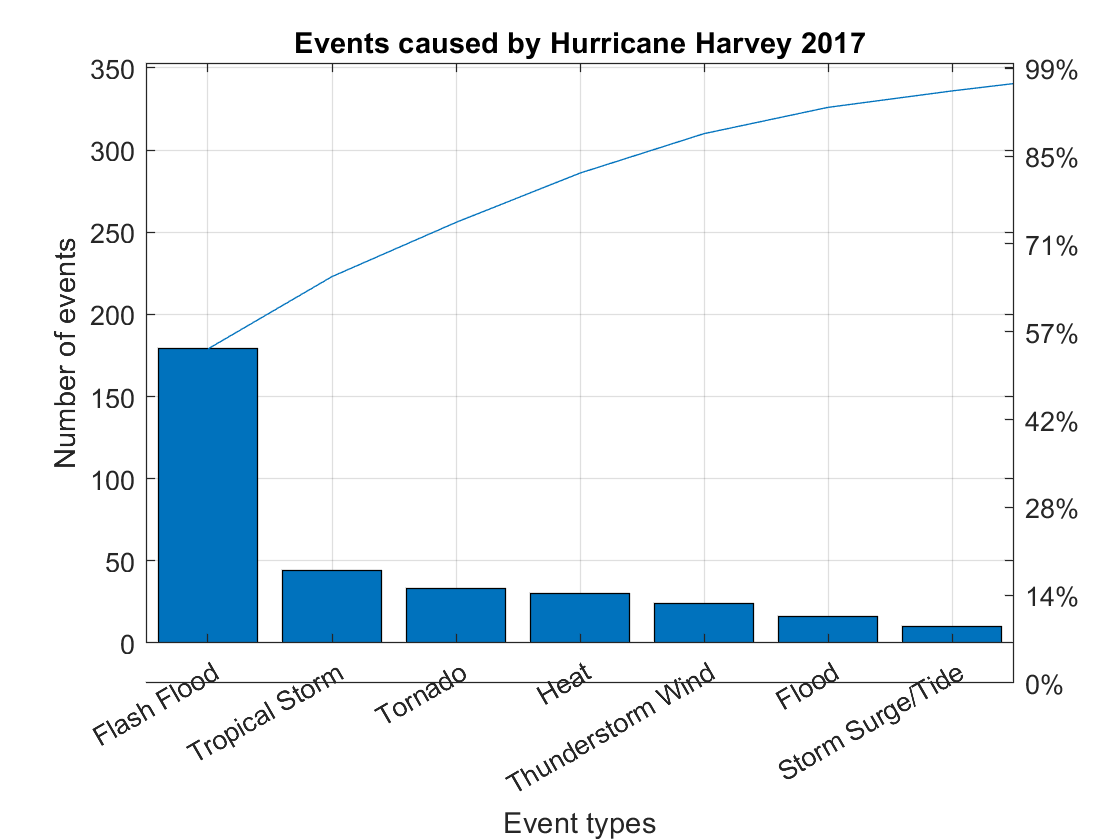

figure
pareto(HarveyEventTypes.GroupCount,HarveyEventTypes.Event_Type)
% axes 1
grid on
title('Events caused by Hurricane Harvey 2017')
xlabel('Event types')
ylabel('Number of events')

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

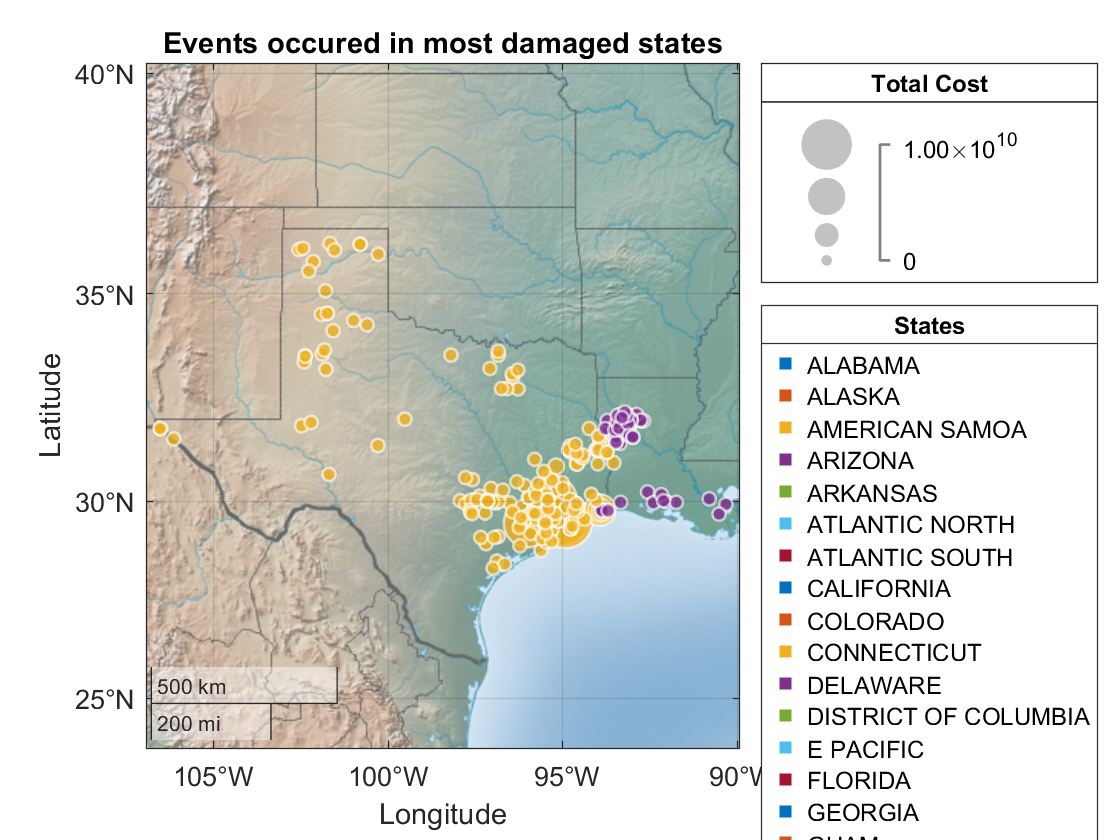

clf, figure % my legend has error and I don't know how to solve it :(
states = HurricaneEvents(ismember(HurricaneEvents.State,totalCostByStates.State([1 2])),:);
geobubble(states,"Begin_Lat","Begin_Lon",SizeVariable="Total_Cost",ColorVariable="State", ...
    LegendVisible="on",Title='Events occured in most damaged states',Basemap='colorterrain', ...
    ColorLegendTitle="States",SizeLegendTitle="Total Cost") 

## Analysis

### Three Counties with Most Events in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 1.

state1Events = HurricaneEvents(HurricaneEvents.State==State1,:);
top3CountiesState1 = groupsummary(state1Events,"CZ_Name","sum","Property_Cost");
top3eventCountiesState1 = sortrows(top3CountiesState1,"GroupCount","descend","MissingPlacement","last");
top3eventCountiesState1 = top3eventCountiesState1(1:3,{'CZ_Name','GroupCount'})

top3eventCountiesState1 = 3×2 table
     CZ_Name     GroupCount
    _________    __________

    HARRIS           21    
    GALVESTON        17    
    FORT BEND        13    


### Three Counties with Most Events in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

state2Events = HurricaneEvents(HurricaneEvents.State==State2,:);
top3CountiesState2 = groupsummary(state2Events,"CZ_Name","sum","Property_Cost");
top3eventCountiesState2 = sortrows(top3CountiesState2,"GroupCount","descend","MissingPlacement","last");
top3eventCountiesState2 = top3eventCountiesState2(1:3,{'CZ_Name','GroupCount'})

top3eventCountiesState2 = 3×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    


### Three Counties with Highest Property Cost in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 1. *Be sure to include the dollar amount*. 

top3propertyCostCountiesState1 = sortrows(top3CountiesState1,"sum_Property_Cost", ...
    "descend","MissingPlacement","last");
top3propertyCostCountiesState1 = top3propertyCostCountiesState1(1:3, ...
    {'CZ_Name','sum_Property_Cost'})

top3propertyCostCountiesState1 = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    GALVESTON             2e+10    
    FORT BEND        1.6004e+10    
    MONTGOMERY          1.4e+10    


### Three Counties with Highest Property Cost in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 2. *Be sure to include the dollar amount*. 

top3propertyCostCountiesState2 = sortrows(top3CountiesState2,"sum_Property_Cost", ...
    "descend","MissingPlacement","last");
top3propertyCostCountiesState2 = top3propertyCostCountiesState2(1:3, ...
    {'CZ_Name','sum_Property_Cost'})

top3propertyCostCountiesState2 = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    CALCASIEU            6e+07     
    BEAUREGARD         1.5e+07     
    ACADIA               2e+05     


## Conclusions and Recommendations.

Conclusion: It is best to provide allocate support for Galveston, Fort Bend, Montgomery counties in Texas first because the damaged property cost is the highest. Harris, Galveston, and Fort Bend are the states that need support regularly after treating the first 3 states in emergency. The same strategy applies to State 2, which is Louisiana.